# AuE-6600 | Dynamic Performance of Vehicles

## Homework 3

### Problem 1

Based on the brush model, the load of the tire is 5200 N, the contact patch length of the tires is 10 cm, the lateral slip is 0.0775, and the lateral stiffness of the tire is cy = 1250 N/cm2. Assume a friction coefficient of μ=0.91.

A. Calculate the force, 𝐹𝑦, under this lateral slip assuming a sinusoidal pressure distribution as shown below. Comment on the potential position of 𝑥𝑠 and is there a discontinuity? 

B. Compare this resulting lateral force with the one resulting from the parabolic model. Plot the lateral force 𝐹𝑦, over a range of slip angles, for both pressure distributions.

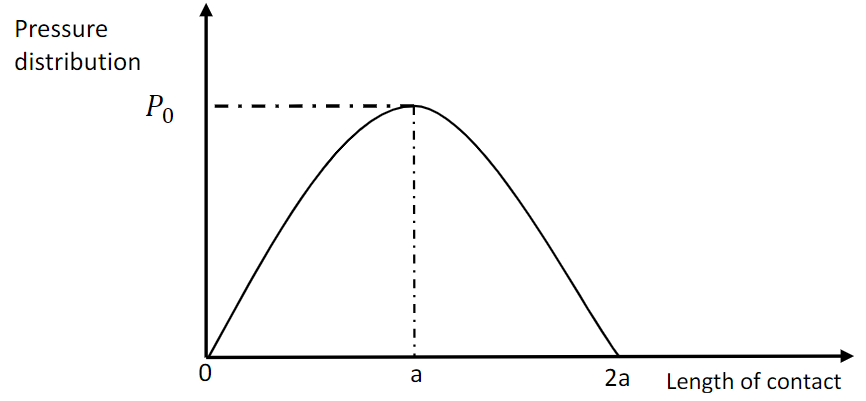

C. Comment about the transition point for the following bilinear distribution (Fig 2) and how it affects sliding region.

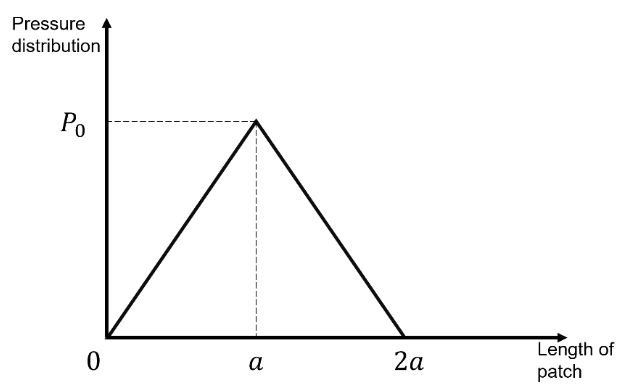

### Solution 1

A. Calculate the force, 𝐹𝑦, under this lateral slip assuming a sinusoidal pressure distribution as shown below. Comment on the potential position of 𝑥𝑠 and is there a discontinuity? 

% Given
Fz = 5200; % N
a = 5; % cm
a = a/100; % m
Sy = 0.0775;
cy = 1250; % N/cm2
cy = cy *1e4; % N/m2
u = 0.91;
% Deflection profiles for uniform and sinusoidal pressure distributions
x = linspace(0,2*a,100);
Yu = Sy*x;
Ys = ((pi*u*Fz)/(4*a*cy))*(sin((pi*x)/(2*a))); % Refer last pages of PDF for derivation
% Polyfit
x_Yu_poly = polyfit(x,Yu,1);
x_Ys_poly = polyfit(x,Ys,5); % 5th order Taylor's series expansion matches sine curve pretty well
% Find xs
xs = x(x>0); % xs>0 -- neglect the initial intersection point at x=0
xs = xs(abs(polyval(x_Yu_poly,xs)-polyval(x_Ys_poly,xs))<1e-4); % Both polyfits must have nearly same value at x=xs
fprintf("xs for sinusoidal pressure distribution is %.4f m",xs)

xs for sinusoidal pressure distribution is 0.0667 m

xs will be the x value corresponding to the intersection point of line and sinusoidal curve. There is no discontinuity for xs since sine curve is continuous.

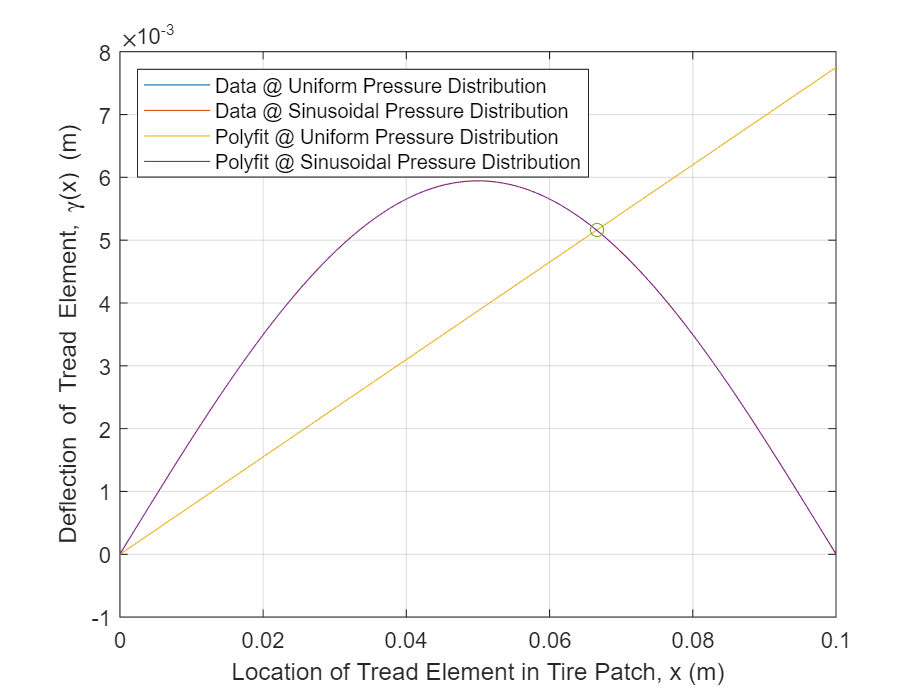

% Plot
figure(1)
plot(x,Yu)
hold on
plot(x,Ys)
plot(x,polyval(x_Yu_poly,x))
plot(x,polyval(x_Ys_poly,x))
plot(xs,polyval(x_Yu_poly,xs),'o')
grid on
xlabel('Location of Tread Element in Tire Patch, x (m)'); ylabel('Deflection of Tread Element, \gamma(x) (m)');
legend('Data @ Uniform Pressure Distribution','Data @ Sinusoidal Pressure Distribution','Polyfit @ Uniform Pressure Distribution','Polyfit @ Sinusoidal Pressure Distribution','Location','NW')
hold off

Fy_s = cy * (diff(polyval(polyint(x_Yu_poly),[0,xs])) + diff(polyval(polyint(x_Ys_poly),[xs,2*a])));
fprintf("Fy for sinusoidal pressure distribution is %.4f kN",Fy_s/1e3)

Fy for sinusoidal pressure distribution is 3.3359 kN

B. Compare this resulting lateral force with the one resulting from the parabolic model. Plot the lateral force 𝐹𝑦, over a range of slip angles, for both pressure distributions.

theta = (2*a^2*cy)/(3*u*Fz);
Fy_p = u*Fz*((3*theta*Sy)-(3*theta^2*Sy^2)+(theta^3*Sy^3));
fprintf("Fy for parabolic pressure distribution is %.4f kN",Fy_p/1e3)

Fy for parabolic pressure distribution is 3.3790 kN

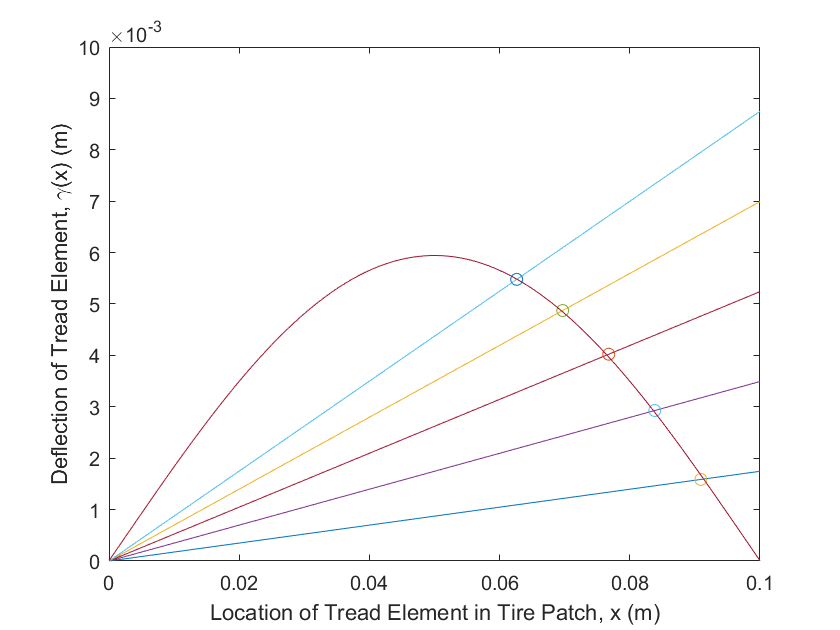

Fy_p = [];
Fy_s = [];
for SA=1:5 % Multiple slip angles
    Sy = tand(SA); % Lateral slip
    % Calculate Fy for parabolic pressure distribution:
    Fy_p(end+1) = u*Fz*((3*theta*Sy)-(3*theta.^2*Sy.^2)+(theta.^3*Sy.^3));
    % Calculate Fy for sinusoidal pressure distribution:
    x = linspace(0,2*a,100);
    Yu = Sy*x;
    Ys = ((pi*u*Fz)/(4*a*cy))*(sin((pi*x)/(2*a))); % Refer last pages of PDF for derivation
    x_Yu_poly = polyfit(x,Yu,1);
    x_Ys_poly = polyfit(x,Ys,5);
    figure(2)
    plot(x,polyval(x_Yu_poly,x))
    hold on
    plot(x,polyval(x_Ys_poly,x))
    xlabel('Location of Tread Element in Tire Patch, x (m)'); ylabel('Deflection of Tread Element, \gamma(x) (m)');
    xs = x(x>0);
    xs = xs(abs(polyval(x_Yu_poly,xs)-polyval(x_Ys_poly,xs))<1e-4);
    plot(xs,polyval(x_Yu_poly,xs),'o')
    Fy_s(end+1) = cy * (diff(polyval(polyint(x_Yu_poly),[0,xs])) + diff(polyval(polyint(x_Ys_poly),[xs,2*a])));
end
hold off

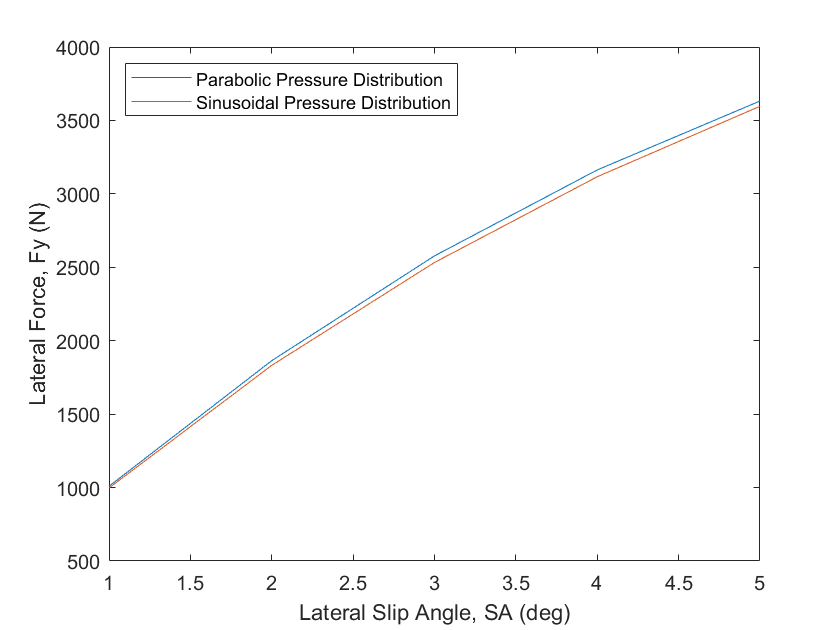

% Plot
SA=1:5;
figure(3)
plot(SA,Fy_p)
hold on
plot(SA,Fy_s)
xlabel('Lateral Slip Angle, SA (deg)'); ylabel('Lateral Force, Fy (N)');
legend('Parabolic Pressure Distribution','Sinusoidal Pressure Distribution','Location','NW')
hold off

C. Comment about the transition point for the following bilinear distribution (Fig 2) and how it affects sliding region.

The transition point `xs` can lie between (`a,` `2a]` depending on the slip angle. Any value of slip angle above this will cause the entire tire patch to slide (i.e. no sticking region), since the tangent to the curve will be nothing but the left side of the triangle or outside of it.

### Problem 2

This problem asks you to fit the same tire data that was used in Homework Assignment #2 (details below) with a version of the Nondimensional Tire Model described in class and in chapter 14. Do the following for data at 0 deg inclination angle, 12 psi inflation pressure, 25 mph roadway speed and positive slip angles (i.e., left turn data only):

1. Apply Nondimensional Tire Model transformations to lateral force and slip angle. Plot nondimensional lateral force vs. nondimensional slip angle.

2. Add a plot of the Magic Formula over the data in question #1. Use the following coefficients:

- B = 0.6000

- C = 1.6667

- D = 1.0000

- E = 0.2000

3. How do these coefficients compare with the one derived from the plot in question #1 and from the relationships given in class?

4. Expand the Nondimensional Model at the five measured normal loads. Create a plot of lateral force vs. slip angle, showing both the measured data and the model predictions.

5. Also expand the Nondimensional Model at –200, –300 and –400 lb normal load. Plot the result on the same figure as question #4

**Details of the collected data from Homework Assignment #2:**

Raw tire data collected on a small Formula SAE racing tire at the Calspan Tire Research Facility* is provided in two files on the Canvas website. Both files contain the same data, one is in `.mat` format and one is a tab-delimited `.dat` file. You may use either file to complete this homework. In MATLAB, use the command `load tireF15.mat` to introduce the variables to the workspace.The tab delimited `.dat` file is well-suited for import into Excel. There are several ways to import the data. Opening the .dat file with Excel should work. If all the contents appear in the first column use the “Text to Columns” menu item to parse the file into individual columns. Symbols and units used in the file are:

- ET = Elapsed Time of the test, sec

- V = Roadway velocity, kph

- SA = Slip Angle, deg

- IA = Inclination Angle, deg

- P = Inflation Pressure, kPa

- FZ = Normal Load, N

- FY = Lateral Force, N

- MX = Overturning Moment, N-m

- MZ = Aligning Torque, N-m

- RL = Loaded Radius, cm

The data is one run from a longer test. It has been collected during a series of slip angle sweeps at various operating conditions. Since this is “real world” data it also contains noise, target error and effects from difficult (or impossible) to control variables such as temperature, tire wear, etc.

You may wish to make the following plots to help you understand the test sequence. These should not be submitted with this homework assignment. Try: Roadway speed vs. time. Inclination angle vs. time. Slip angle vs. time. Normal Load vs. time. Inflation Pressure vs. time.

When reviewing the data, note that there are a total of six target loads, each 50 lb apart. While the data is presented in SI units, the native units for the Calspan Tire Research Facility are US Customary Units. Thus, for simplicity the test was designed around common USCS values, such as 50 lb load spacing, 25 mph, inflation pressures of 8 and 12 psi, etc. Target values will not have “round” SI values.

*Data for this assignment was collected by the Formula SAE Tire Test Consortium at the Calspan Corporation Tire Research Facility in Buffalo, NY.

### Solution 2

load('tireF15.mat')

0. Test plots (not for submission) - Roadway speed vs. time. Inclination angle vs. time. Slip angle vs. time. Normal Load vs. time. Inflation Pressure vs. time.

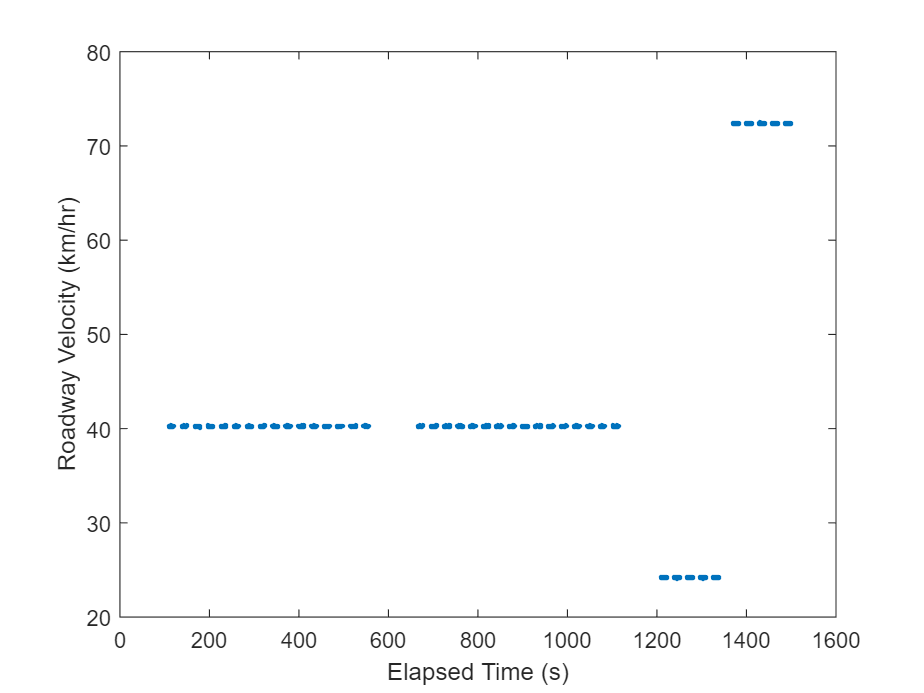

figure(1)
plot(ET, V, '.');
xlabel('Elapsed Time (s)'); ylabel('Roadway Velocity (km/hr)');

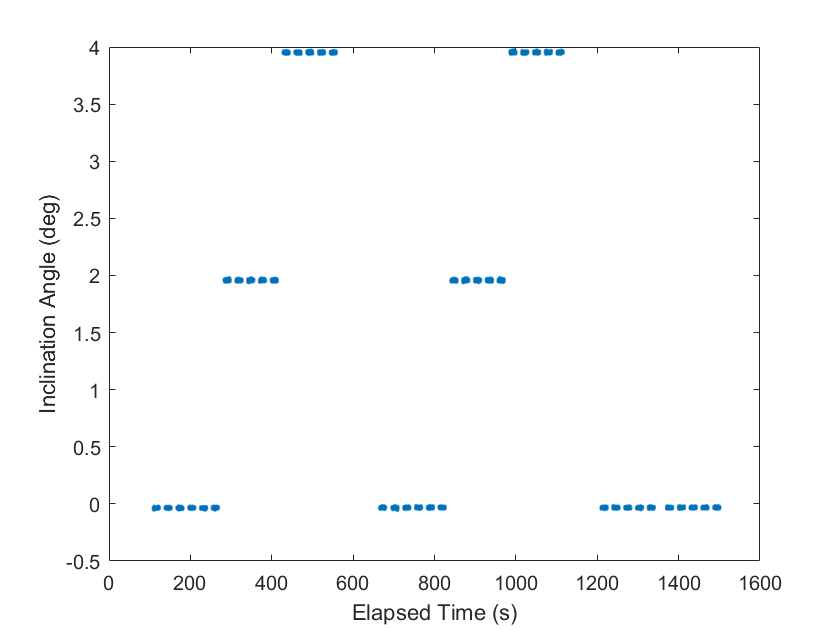

figure(2)
plot(ET, IA, '.');
xlabel('Elapsed Time (s)'); ylabel('Inclination Angle (deg)');

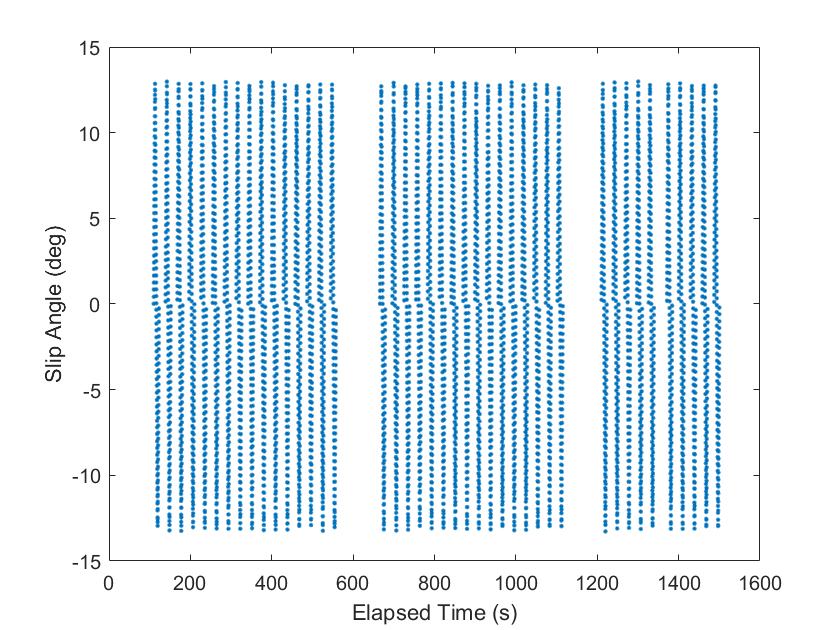

figure(3)
plot(ET, SA, '.');
xlabel('Elapsed Time (s)'); ylabel('Slip Angle (deg)');

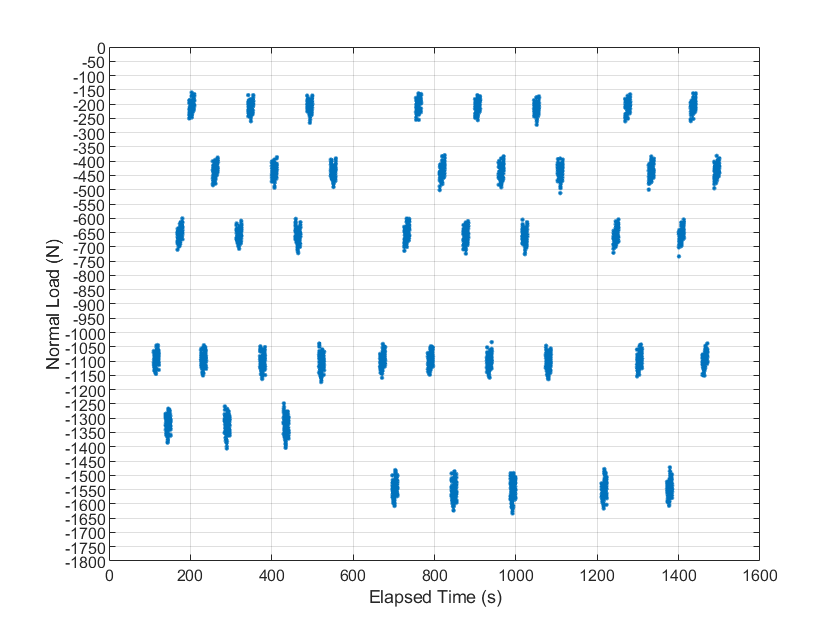

figure(4)
plot(ET, FZ, '.');
xlabel('Elapsed Time (s)'); ylabel('Normal Load (N)');
set(gca, 'ytick', -1800:50:0, 'FontSize', 8);
grid on;

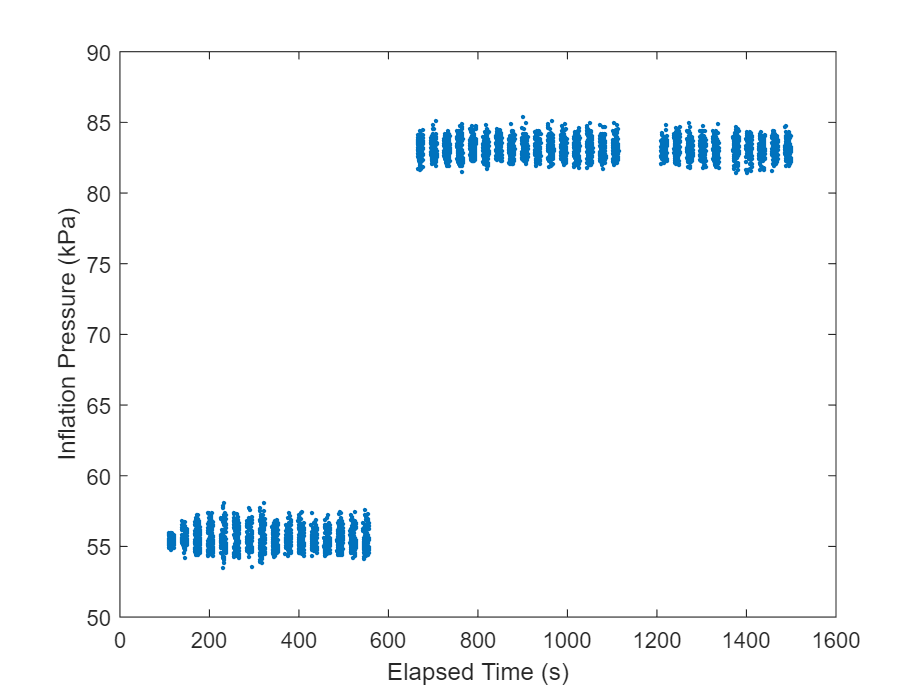

figure(5)
plot(ET, P, '.');
xlabel('Elapsed Time (s)'); ylabel('Inflation Pressure (kPa)');

% Data preprocessing (for questions 1-5, only use the data at 0 deg inclination angle, 12 psi inflation pressure, 25 mph roadway speed and positive slip angles (i.e., left turn data only))
IA_desired = 0; % deg
P_desired = 12; % psi
P_desired = P_desired * 6.895; % kPa
V_desired = 25; % mph
V_desired = V_desired * 1.609344; % kmph
% SA_desired >= 0 % deg
ET_desired_indices = [];

for i = 1:length(ET)
    if abs(IA(i)-IA_desired)<=0.5 && abs(P(i)-P_desired)<=5 && abs(V(i)-V_desired)<=1 && SA(i)>0
        ET_desired_indices(end+1) = i; % Desired time instances based on given "desired" conditions
    end
end
% Visually observing the data, we can see that there are 6 different normal load (FZ) values
FZ_50_indices = find((abs(FZ) >= min(abs(FZ))) & (abs(FZ) <= 300)); % FZ ~ 50 lb
FZ_100_indices = find((abs(FZ) > 300) & (abs(FZ) <= 550)); % FZ ~ 100 lb
FZ_150_indices = find((abs(FZ) > 550) & (abs(FZ) <= 750)); % FZ ~ 150 lb
% No data for FZ ~ 200 lb
FZ_250_indices = find((abs(FZ) > 1000) & (abs(FZ) <= 1200)); % FZ ~ 250 lb
FZ_300_indices = find((abs(FZ) > 1200) & (abs(FZ) <= 1450)); % FZ ~ 300 lb
FZ_350_indices = find((abs(FZ) > 1450) & (abs(FZ) <= max(abs(FZ)))); % FZ ~ 350 lb

1. Apply Nondimensional Tire Model transformations to lateral force and slip angle. Plot nondimensional lateral force vs. nondimensional slip angle.

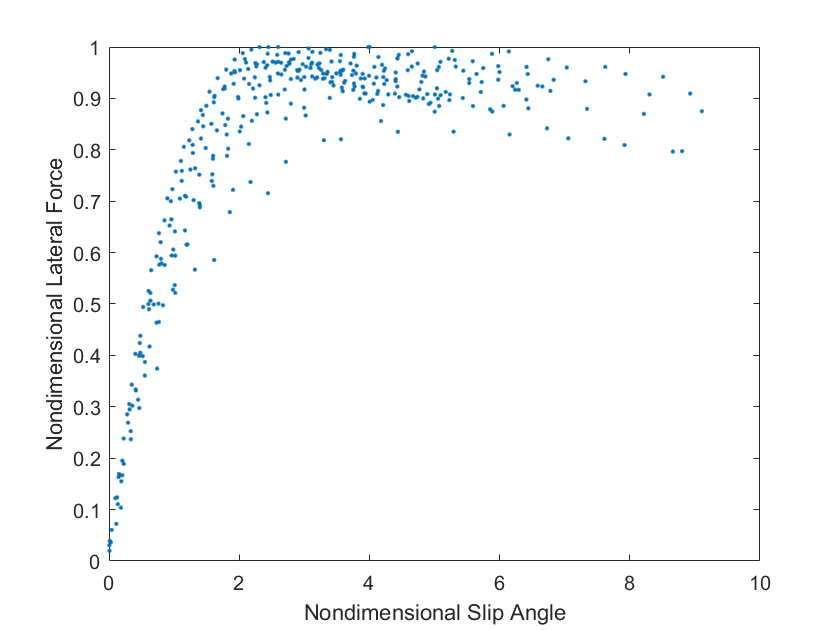

% Extract FZ and segregate FY and SA data based on corresponding desired FZ indices
[FZ_50_desired,FZ_100_desired,FZ_150_desired,FZ_250_desired,FZ_300_desired,FZ_350_desired] = deal([]); % N
[FY_50,FY_100,FY_150,FY_250,FY_300,FY_350] = deal([]); % N
[SA_50,SA_100,SA_150,SA_250,SA_300,SA_350] = deal([]); % rad (convert from degrees to radians in following loops)
for i = 1:length(ET_desired_indices)
    if ismember(ET_desired_indices(i), FZ_50_indices)
        FZ_50_desired(end+1) = FZ(ET_desired_indices(i));
        FY_50(end+1) = FY(ET_desired_indices(i));
        SA_50(end+1) = deg2rad(SA(ET_desired_indices(i)));
    elseif ismember(ET_desired_indices(i), FZ_100_indices)
        FZ_100_desired(end+1) = FZ(ET_desired_indices(i));
        FY_100(end+1) = FY(ET_desired_indices(i));
        SA_100(end+1) = deg2rad(SA(ET_desired_indices(i)));
    elseif ismember(ET_desired_indices(i), FZ_150_indices)
        FZ_150_desired(end+1) = FZ(ET_desired_indices(i));
        FY_150(end+1) = FY(ET_desired_indices(i));
        SA_150(end+1) = deg2rad(SA(ET_desired_indices(i)));
    elseif ismember(ET_desired_indices(i), FZ_250_indices)
        FZ_250_desired(end+1) = FZ(ET_desired_indices(i));
        FY_250(end+1) = FY(ET_desired_indices(i));
        SA_250(end+1) = deg2rad(SA(ET_desired_indices(i)));
    elseif ismember(ET_desired_indices(i), FZ_300_indices) % [NOTE: FZ=300 values are not in range of ET_desired_indices]
        FZ_300_desired(end+1) = FZ(ET_desired_indices(i));
        FY_300(end+1) = FY(ET_desired_indices(i));
        SA_300(end+1) = deg2rad(SA(ET_desired_indices(i)));
    elseif ismember(ET_desired_indices(i), FZ_350_indices)
        FZ_350_desired(end+1) = FZ(ET_desired_indices(i));
        FY_350(end+1) = FY(ET_desired_indices(i));
        SA_350(end+1) = deg2rad(SA(ET_desired_indices(i)));
    else
        fprintf("ET index does not correspond to any FZ value!") % Sanity check
    end
end

% Non-dimensional tire model transformation

% Compute mean FZ values which can be used in further calculations as a single FZ value
FZ_50 = mean(FZ_50_desired);
FZ_100 = mean(FZ_100_desired);
FZ_150 = mean(FZ_150_desired);
FZ_250 = mean(FZ_250_desired);
FZ_350 = mean(FZ_350_desired);
% Compute u for different FZ values
u_50 = abs(min(FY_50)/FZ_50);
u_100 = abs(min(FY_100)/FZ_100);
u_150 = abs(min(FY_150)/FZ_150);
u_250 = abs(min(FY_250)/FZ_250);
u_350 = abs(min(FY_350)/FZ_350);
% Compute c for different FZ values
poly_50 = polyfit(SA_50,FY_50,9); % 1. Fit polinomials to FY vs SA data
poly_100 = polyfit(SA_100,FY_100,9);
poly_150 = polyfit(SA_150,FY_150,9);
poly_250 = polyfit(SA_250,FY_250,9);
poly_350 = polyfit(SA_350,FY_350,9);
poly_50_prime = polyder(poly_50); % 2. Take derivatives of polinomials fit to FY vs SA data
poly_100_prime = polyder(poly_100);
poly_150_prime = polyder(poly_150);
poly_250_prime = polyder(poly_250);
poly_350_prime = polyder(poly_350);
c_50 = polyval(poly_50_prime, 0); % 3. Evaluate derivatives at SA = 0 rad (this is the cornering stiffness)
c_100 = polyval(poly_100_prime, 0);
c_150 = polyval(poly_150_prime, 0);
c_250 = polyval(poly_250_prime, 0);
c_350 = polyval(poly_350_prime, 0);

% (i) FY_bar
% Compute FY_bar values for each normal load (FZ)
for i = 1:length(FY_50)
    FY_50_bar(i) = FY_50(i)/(u_50*FZ_50);
end
for i = 1:length(FY_100)
    FY_100_bar(i) = FY_100(i)/(u_100*FZ_100);
end
for i = 1:length(FY_150)
    FY_150_bar(i) = FY_150(i)/(u_150*FZ_150);
end
for i = 1:length(FY_250)
    FY_250_bar(i) = FY_250(i)/(u_250*FZ_250);
end
for i = 1:length(FY_350)
    FY_350_bar(i) = FY_350(i)/(u_350*FZ_350);
end
% Concatenate individual FY_bar values for each normal load (FZ) into a single array
FY_bar = cat(2,FY_50_bar,FY_100_bar,FY_150_bar,FY_250_bar,FY_350_bar);

% (ii) SA_bar
% Compute SA_bar values for each normal load (FZ)
for i = 1:length(SA_50)
    SA_50_bar(i) = (c_50*tan(SA_50(i)))/(u_50*FZ_50);
end
for i = 1:length(SA_100)
    SA_100_bar(i) = (c_100*tan(SA_100(i)))/(u_100*FZ_100);
end
for i = 1:length(SA_150)
    SA_150_bar(i) = (c_150*tan(SA_150(i)))/(u_150*FZ_150);
end
for i = 1:length(SA_250)
    SA_250_bar(i) = (c_250*tan(SA_250(i)))/(u_250*FZ_250);
end
for i = 1:length(SA_350)
    SA_350_bar(i) = (c_350*tan(SA_350(i)))/(u_350*FZ_350);
end
% Concatenate individual SA_bar values for each normal load (FZ) into a single array
SA_bar = cat(2,SA_50_bar,SA_100_bar,SA_150_bar,SA_250_bar,SA_350_bar);

% Fit polinomial to FY_bar vs SA_bar data (nondimensional data)
% FY_SA_bar_poly = polyfit(SA_bar,FY_bar,7);

% Plot FY_bar vs SA_bar data (nondimensional data) and the polinomial fit
plot(SA_bar,FY_bar,'.')
hold on
% plot(SA_bar,polyval(FY_SA_bar_poly,SA_bar))
xlabel("Nondimensional Slip Angle")
ylabel("Nondimensional Lateral Force")
% legend("Measured Data","Polynomial Fit", 'Location','SE')
hold off

2. Add a plot of the Magic Formula over the data in question #1. Use the following coefficients: B = 0.6000, C = 1.6667, D = 1.0000, E = 0.2000

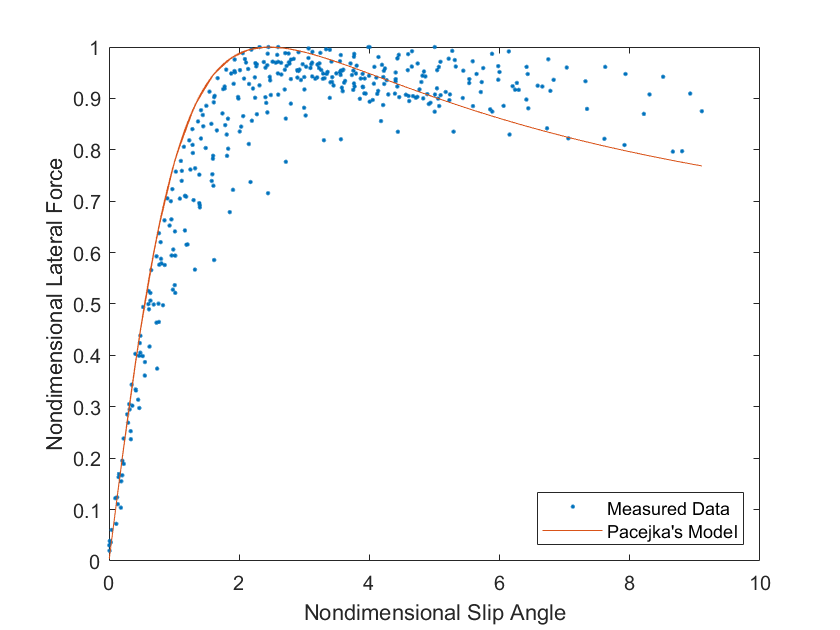

% Plot FY_bar vs SA_bar data (nondimensional data)
figure()
plot(SA_bar,FY_bar,'.')
hold on
% Plot the polinomial fit to FY_bar vs SA_bar data (nondimensional data)
% plot(SA_bar,polyval(FY_SA_bar_poly,SA_bar))
% Pacejka's magic tire model
B = 0.6000;
C = 1.6667;
D = 1.0000;
E = 0.2000;
FY_pacejka = D*sin(C*atan((B*SA_bar)-E*((B*SA_bar)-atan((B*SA_bar)))));
% Plot the Pacejka's magic tire model
plot(SA_bar,FY_pacejka, '-')
xlabel("Nondimensional Slip Angle")
ylabel("Nondimensional Lateral Force")
legend("Measured Data","Pacejka's Model", 'Location','SE')
hold off

3. How do these (B = 0.6000, C = 1.6667, D = 1.0000, E = 0.2000) coefficients compare with the one derived from the plot in question #1 and from the relationships given in class?

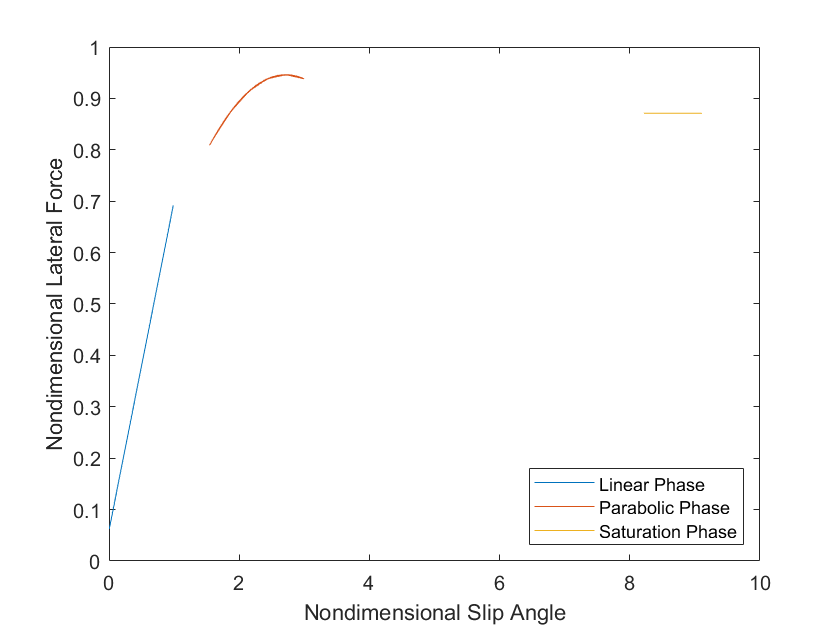

% Fit polynomials to different phases of the FY_bar vs SA_bar data
FY_SA_bar_poly_1 = polyfit(SA_bar(SA_bar>=0 & SA_bar<=1),FY_bar(SA_bar>=0 & SA_bar<=1),1); % Linear phase (Straight line for small SA)
FY_SA_bar_poly_2 = polyfit(SA_bar(SA_bar>=1.5 & SA_bar<=3),FY_bar(SA_bar>=1.5 & SA_bar<=3),2); % Parabolic phase (Parabola around peak FY)
FY_SA_bar_poly_3 = mean(FY_bar(SA_bar>=8 & SA_bar<=10)); % Saturation phase (flat asymptote in for large SA)

% Plot fit polynomials on FY_bar vs SA_bar data
figure()
plot(SA_bar(SA_bar>=0 & SA_bar<=1),polyval(FY_SA_bar_poly_1,SA_bar(SA_bar>=0 & SA_bar<=1)))
hold on
plot(SA_bar(SA_bar>=1.5 & SA_bar<=3),polyval(FY_SA_bar_poly_2,SA_bar(SA_bar>=1.5 & SA_bar<=3)))
plot(SA_bar(SA_bar>=8 & SA_bar<=10),polyval(FY_SA_bar_poly_3,SA_bar(SA_bar>=8 & SA_bar<=10)))
xlabel("Nondimensional Slip Angle")
ylabel("Nondimensional Lateral Force")
legend("Linear Phase","Parabolic Phase","Saturation Phase",'Location','SE')
hold off

% Derive Pacejka's coefficients
D_derived = max(polyval(FY_SA_bar_poly_2,SA_bar(SA_bar>=1.5 & SA_bar<=3))); % D = Peak value along y
ys = mean(polyval(FY_SA_bar_poly_3,(SA_bar>=8 & SA_bar<=10))); % ys = value of y @ large x (saturation)
C_derived = 1+(1-((2/pi)*asin(ys/D))); % C = 1 +/- (1-((2/pi)*asin(ys/D))) we take C = 1+(1-((2/pi)*asin(ys/D))) to help calculate E for C > 1
BCD = polyval(polyder(FY_SA_bar_poly_1),0); % BCD = slope (derivative) @ x=0,y=0
B_derived = BCD/(C_derived*D_derived); % B = BCD/CD
xm = fzero(@(x) polyval(polyder(FY_SA_bar_poly_2), x), 0); % xm = x coordinate corresponding to peak value along y (i.e. D) i.e. x for which slope = 0 (maxima), starting from x = 0
E_derived = ((B_derived*xm)-tan(pi/(2*C_derived)))/((B_derived*xm)-atan(B_derived*xm)); % E_derived = ((B_derived*xm)-tan(pi/(2*C_derived)))/((B_derived*xm)-atan(B_derived*xm))
ys_check = D_derived*sin((pi*C_derived)/2); % Check/verification

% First row = given coefficients
% Second row = derived coefficients
Pacejka_Parameters = [B C D E; B_derived C_derived D_derived E_derived]

Pacejka_Parameters =     0.6000    1.6667    1.0000    0.2000
    0.5100    1.3267    0.9462   -2.4363


4. Expand the Nondimensional Model at the five measured normal loads. Create a plot of lateral force vs. slip angle, showing both the measured data and the model predictions.

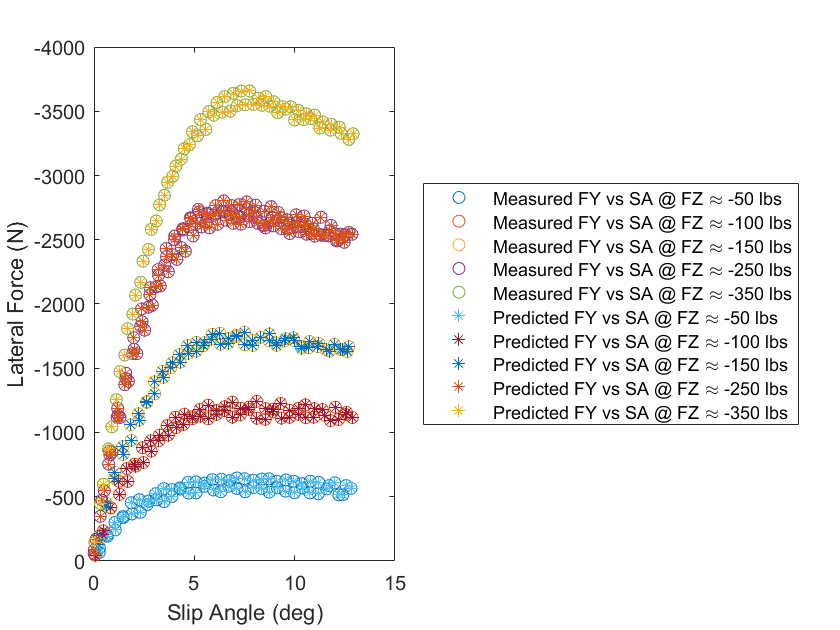

% Expanding nondimensional tire model at FZ
% FY = FY_bar(@FZ) * u(@FZ) * FZ

% Calculate FY by expanding nondimensional tire model at each measured FZ = [50,100,150,250,350] lbs
for i = 1:length(FZ_50_desired)
    FY_50_predicted(i) = FY_50_bar(i)*u_50*FZ_50;
end
for i = 1:length(FZ_100_desired)
    FY_100_predicted(i) = FY_100_bar(i)*u_100*FZ_100;
end
for i = 1:length(FZ_150_desired)
    FY_150_predicted(i) = FY_150_bar(i)*u_150*FZ_150;
end
for i = 1:length(FZ_250_desired)
    FY_250_predicted(i) = FY_250_bar(i)*u_250*FZ_250;
end
for i = 1:length(FZ_350_desired)
    FY_350_predicted(i) = FY_350_bar(i)*u_350*FZ_350;
end

% Plot FY vs SA, showing both the measured data and the model predictions
figure()
% Measured data
plot(rad2deg(SA_50),FY_50,'o')
hold on
plot(rad2deg(SA_100),FY_100,'o')
plot(rad2deg(SA_150),FY_150,'o')
plot(rad2deg(SA_250),FY_250,'o')
plot(rad2deg(SA_350),FY_350,'o')
% Model predictions
plot(rad2deg(SA_50),FY_50_predicted,'*')
plot(rad2deg(SA_100),FY_100_predicted,'*')
plot(rad2deg(SA_150),FY_150_predicted,'*')
plot(rad2deg(SA_250),FY_250_predicted,'*')
plot(rad2deg(SA_350),FY_350_predicted,'*')
set(gca, 'YDir','reverse') % Invert Y-axis to match RCVD convention
xlabel("Slip Angle (deg)")
ylabel("Lateral Force (N)")
legend("Measured FY vs SA @ FZ \approx -50 lbs","Measured FY vs SA @ FZ \approx -100 lbs","Measured FY vs SA @ FZ \approx -150 lbs","Measured FY vs SA @ FZ \approx -250 lbs","Measured FY vs SA @ FZ \approx -350 lbs", ...
       "Predicted FY vs SA @ FZ \approx -50 lbs","Predicted FY vs SA @ FZ \approx -100 lbs","Predicted FY vs SA @ FZ \approx -150 lbs","Predicted FY vs SA @ FZ \approx -250 lbs","Predicted FY vs SA @ FZ \approx -350 lbs", ...
       "Location","EO")
hold off

5. Also expand the Nondimensional Model at –200, –300 and –400 lb normal load. Plot the result on the same figure as question #4

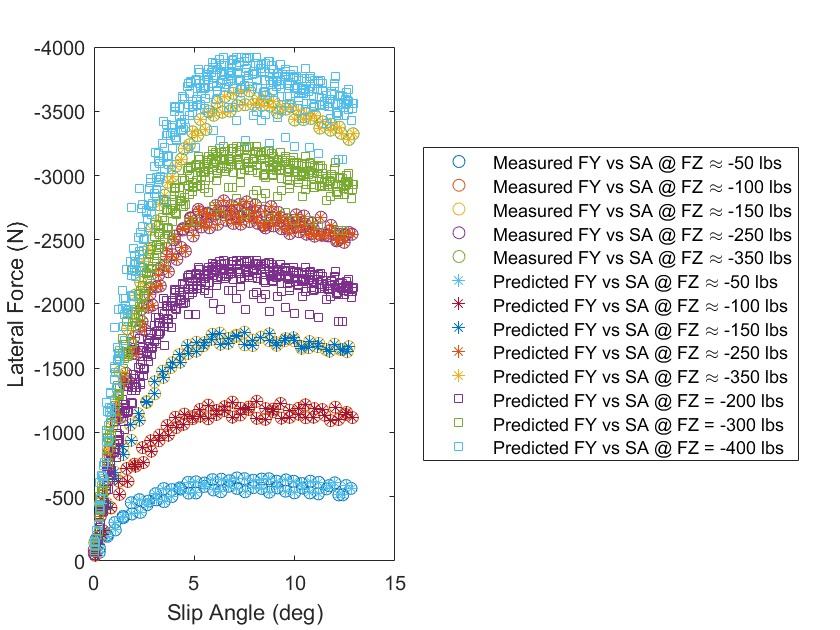

FZ_200 = -200*4.448; % lbs to N
FZ_300 = -300*4.448; % lbs to N
FZ_400 = -400*4.448; % lbs to N

% Cornering stiffness
% Fit polinomials to FY vs SA data (for each normal load FZ)
poly_50 = polyfit(SA_50,FY_50,9);
poly_100 = polyfit(SA_100,FY_100,9);
poly_150 = polyfit(SA_150,FY_150,9);
poly_250 = polyfit(SA_250,FY_250,9);
poly_350 = polyfit(SA_350,FY_350,9);
% Take derivatives of polinomials fit to FY vs SA data
poly_50_prime = polyder(poly_50);
poly_100_prime = polyder(poly_100);
poly_150_prime = polyder(poly_150);
poly_250_prime = polyder(poly_250);
poly_350_prime = polyder(poly_350);
% Evaluate derivatives at SA = 0 deg (this is the cornering stiffness)
c_50 = polyval(poly_50_prime, 0);
c_100 = polyval(poly_100_prime, 0);
c_150 = polyval(poly_150_prime, 0);
c_250 = polyval(poly_250_prime, 0);
c_350 = polyval(poly_350_prime, 0);
% Generate table of c vs FZ
c_FZ_table = [FZ_50 FZ_100 FZ_150 FZ_250 FZ_350;
              c_50  c_100  c_150  c_250  c_350];
% Fit polinomial to c vs FZ data
c_FZ_poly = polyfit(c_FZ_table(1,:), c_FZ_table(2,:),3);
% Compute coefficient of friction at FZ = [-200 -300 -400] lbs
c_200 = polyval(c_FZ_poly,FZ_200);
c_300 = polyval(c_FZ_poly,FZ_300);
c_400 = polyval(c_FZ_poly,FZ_400);
% Plot c vs FZ
% figure()
% plot(c_FZ_table(1,:), c_FZ_table(2,:), '--o')
% hold on
% plot(c_FZ_table(1,:),polyval(c_FZ_poly,c_FZ_table(1,:)))
% xlabel("Normal Load (N)")
% ylabel("Cornering Stiffness (N/rad)")
% set(gca, 'XDir','reverse') % Invert X-axis to match RCVD convention
% legend("Measured Data","Polynomial Fit", 'Location','SE')
% hold off

% Coefficient of friction
% Compute u for different FZ values
u_50 = abs(min(FY_50)/FZ_50);
u_100 = abs(min(FY_100)/FZ_100);
u_150 = abs(min(FY_150)/FZ_150);
u_250 = abs(min(FY_250)/FZ_250);
u_350 = abs(min(FY_350)/FZ_350);
% Generate table of u vs FZ
u_FZ_table = [FZ_50 FZ_100 FZ_150 FZ_250 FZ_350;
              u_50  u_100  u_150  u_250  u_350];
% Fit polinomial to u vs FZ data
u_FZ_poly = polyfit(u_FZ_table(1,:), u_FZ_table(2,:),1);
% Compute coefficient of friction at FZ = [-200 -300 -400] lbs
u_200 = polyval(u_FZ_poly,FZ_200);
u_300 = polyval(u_FZ_poly,FZ_300);
u_400 = polyval(u_FZ_poly,FZ_400);
% Plot u vs FZ
% figure()
% plot(u_FZ_table(1,:), u_FZ_table(2,:), '--o')
% hold on
% plot(u_FZ_table(1,:),polyval(u_FZ_poly,u_FZ_table(1,:)))
% xlabel("Normal Load (N)")
% ylabel("Coefficient of Friction")
% ylim([0,3.5])
% set(gca, 'XDir','reverse') % Invert X-axis to match RCVD convention
% legend("Measured Data","Polynomial Fit", 'Location','SE')
% hold off

% Expanding nondimensional tire model at FZ
% Calculate FY by expanding nondimensional tire model at each FZ = [200,300,400] lbs
% FY = FY_bar(@FZ) * u(@FZ) * FZ
for i = 1:length(SA_bar)
    FY_200_predicted(i) = FY_bar(i)*u_200*FZ_200;
    FY_300_predicted(i) = FY_bar(i)*u_300*FZ_300;
    FY_400_predicted(i) = FY_bar(i)*u_400*FZ_400;
end
% Concatenate individual SA values for each normal load (FZ) into a single array
SA_concatenated = cat(2,SA_50,SA_100,SA_150,SA_250,SA_350);

% Plot FY vs SA, showing both the measured data and the model predictions (for measured as well as unknown data)
figure()
% Measured data
plot(rad2deg(SA_50),FY_50,'o')
hold on
plot(rad2deg(SA_100),FY_100,'o')
plot(rad2deg(SA_150),FY_150,'o')
plot(rad2deg(SA_250),FY_250,'o')
plot(rad2deg(SA_350),FY_350,'o')
% Model predictions for measured data
plot(rad2deg(SA_50),FY_50_predicted,'*')
plot(rad2deg(SA_100),FY_100_predicted,'*')
plot(rad2deg(SA_150),FY_150_predicted,'*')
plot(rad2deg(SA_250),FY_250_predicted,'*')
plot(rad2deg(SA_350),FY_350_predicted,'*')
% Model predictions for unknown data
plot(rad2deg(SA_concatenated),FY_200_predicted,'sq')
plot(rad2deg(SA_concatenated),FY_300_predicted,'sq')
plot(rad2deg(SA_concatenated),FY_400_predicted,'sq')
set(gca, 'YDir','reverse') % Invert Y-axis to match RCVD convention
xlabel("Slip Angle (deg)")
ylabel("Lateral Force (N)")
legend("Measured FY vs SA @ FZ \approx -50 lbs","Measured FY vs SA @ FZ \approx -100 lbs","Measured FY vs SA @ FZ \approx -150 lbs","Measured FY vs SA @ FZ \approx -250 lbs","Measured FY vs SA @ FZ \approx -350 lbs", ...
       "Predicted FY vs SA @ FZ \approx -50 lbs","Predicted FY vs SA @ FZ \approx -100 lbs","Predicted FY vs SA @ FZ \approx -150 lbs","Predicted FY vs SA @ FZ \approx -250 lbs","Predicted FY vs SA @ FZ \approx -350 lbs", ...
       "Predicted FY vs SA @ FZ = -200 lbs","Predicted FY vs SA @ FZ = -300 lbs","Predicted FY vs SA @ FZ = -400 lbs", ...
       "Location","EO")
hold off